## **Reserve-based Maintenance Scheduling**

maintenance_data = xlsread("Demand.xlsx") ;

Declare the optimization problem and define the variables:

periods = size(maintenance_data,1) ;
maintenance_reserve = optimproblem ;
x_vars = optimvar("X",periods, LowerBound= 0, Type="integer") ;
y_vars = optimvar("Y",periods, LowerBound= 0, Type="integer") ;
m_vars = optimvar("M",periods, LowerBound= 0, Type="integer") ;
n_vars = optimvar("N",periods, LowerBound= 0, Type="integer") ;
U = optimvar("U",periods, LowerBound= 0, Type="continuous") ;
Demand = maintenance_data(:,2) ;

Define m_vars and n_vars:

maintenance_reserve.Constraints.m1 = (m_vars(1) == x_vars(1)) ; 
maintenance_reserve.Constraints.n1 = (n_vars(1) == y_vars(1)) ;  
maintenance_reserve.Constraints.m2 = m_vars(2) == x_vars(2) + x_vars(1) ; 
maintenance_reserve.Constraints.mRest = m_vars(3:end) == x_vars(3:end) + x_vars(2:end-1) + x_vars(1:end-2) ; 
maintenance_reserve.Constraints.nRest = n_vars(2:end) == y_vars(2:end) + y_vars(1:end-1); 


Add the dummy constraint:

reserve = optimexpr(periods,1) ;
for i = 1:periods
    reserve(i) = 2200 - 300 .* m_vars(i) - 100 .* n_vars(i) - Demand(i) ;
    %reserve(i) = reserve(i) /  Demand(i) ; 
end

summation = sum(reserve) ;
average = 1/12 * summation ;

dummy_reserve = average - reserve ; 

maintenance_reserve.Constraints.dummy_upper = dummy_reserve <=  U ;
maintenance_reserve.Constraints.dummy_lower = dummy_reserve >= - U ;

Add the constraint on total maintenance for each type:

x_total_maintenance = sum(x_vars) ; 
y_total_maintenance = sum(y_vars) ;  
maintenance_reserve.Constraints.x_total_maintenance ...
    = x_total_maintenance == 6;
maintenance_reserve.Constraints.y_total_maintenance ...
    = y_total_maintenance == 4;

Add the constraint on maximum number of maintenance operations at the same time:

maintenance_reserve.Constraints.max_in_parallel =  m_vars + n_vars <= 3 ; 

Add the constraint on the minimum reserve being equal to the largest two units:

min_reserve = 2200 - 300*m_vars - 100*n_vars - Demand ;
maintenance_reserve.Constraints.min_reserve = min_reserve >= 2*300 ;

Add the constraint on not starting maintenance at the end:

maintenance_reserve.Constraints.m_bound = x_vars(periods-1: periods) == 0 ;
maintenance_reserve.Constraints.n_bound = y_vars(periods) == 0 ;

Define the objective function:

maintenance_reserve.Objective = sum(U) ;

Solve the optimization problem:

[sol,fval] = solve(maintenance_reserve) ;

Solving problem using intlinprog.
LP:                Optimal objective value is 0.000000.                                             

Cut Generation:    Applied 12 Gomory cuts.                                                          
                   Lower bound is 196.114238.                                                       

Heuristics:        Found 6 solutions using total rounding.                                          
                   Upper bound is 616.666667.                                                       
                   Relative gap is 68.09%.                                                         

Heuristics:        Found 1 solution using diving.                                                   
                   Upper bound is 616.666667.                                                       
                   Relative gap is 68.09%.                                                         

Heuristics:        Found 1 solution using rss.         

Plot the results: 

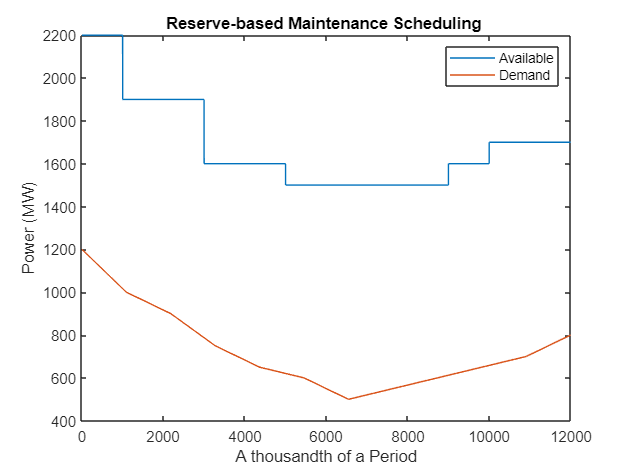

Available = 2200 - 300 * sol.M - 100 * sol.N ;

Available_flat = zeros(periods*1000,1) ; 
Demand_flat = zeros(periods*1000,1) ; 

for i = 1: periods
    Available_flat(1 + 1000*(i-1)) = Available(i) ;
    Demand_flat(1 + 1000*(i-1)) = Demand(i) ; 
    j = 2 + 1000*(i-1) ;
    while(j <= i*1000)
        Available_flat(j) = Available_flat(j-1) ;
        Demand_flat(j) = Demand_flat(j-1) ;
        j = j + 1 ; 
    end
end

plot(1:periods*1000, Available_flat)
hold on 
plot(linspace(1,periods*1000,12),Demand)
hold off

legend(["Available","Demand"])
title("Reserve-based Maintenance Scheduling ")
xlabel("A thousandth of a Period")
ylabel("Power (MW)")

A smoother plot:

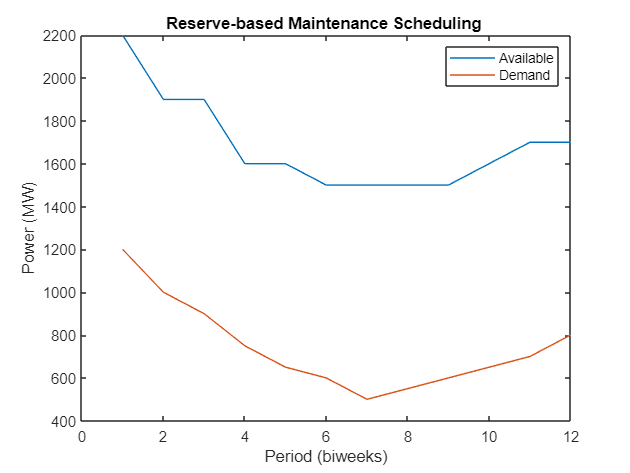

plot(1:periods, Available)
hold on 
plot(linspace(1,periods,12),Demand)
hold off

legend(["Available","Demand"])
title("Reserve-based Maintenance Scheduling ")
xlabel("Period (biweeks)")
ylabel("Power (MW)")

Display the results:

disp("The number of units that start their maintenance at each period: ") ; 

The number of units that start their maintenance at each period: 



for i = 1: periods
    if sol.X(i) == 0
        sol.X(i) = 0 ; % take care of "-0"
    end
    if sol.Y(i) == 0
        sol.Y(i) = 0 ; % take care of "-0"
    end
    disp(sprintf("period %.f: \n",i) );
    disp(sprintf("\t 300 MW: %.f",sol.X(i))) ;
    disp(sprintf("\t 100 MW: %.f",sol.Y(i))) ;
end

period 1: 



	 300 MW: 0


	 100 MW: 0


period 2: 



	 300 MW: 1


	 100 MW: 0


period 3: 



	 300 MW: 0


	 100 MW: 0


period 4: 



	 300 MW: 1


	 100 MW: 0


period 5: 



	 300 MW: 1


	 100 MW: 0


period 6: 



	 300 MW: 0


	 100 MW: 1


period 7: 



	 300 MW: 1


	 100 MW: 0


period 8: 



	 300 MW: 1


	 100 MW: 1


period 9: 



	 300 MW: 0


	 100 MW: 0


period 10: 



	 300 MW: 1


	 100 MW: 0


period 11: 



	 300 MW: 0


	 100 MW: 2


period 12: 



	 300 MW: 0


	 100 MW: 0



disp(sprintf("\n")) ;
disp(sprintf("\n")) ;
disp("The number of units that are under maintenance at each period") ; 

The number of units that are under maintenance at each period


disp("Reminder:") ;

Reminder:


disp(sprintf("\t 300 MW units need 6 weeks (3 periods)")) ;

	 300 MW units need 6 weeks (3 periods)


disp(sprintf("\t 100 MW units need 4 weeks (2 periods)")) ;

	 100 MW units need 4 weeks (2 periods)


disp(sprintf("\n")) ;

for i = 1: periods
    if sol.M(i) == 0
        sol.M(i) = 0 ; % take care of "-0"
    end
    if sol.N(i) == 0
        sol.N(i) = 0 ; % take care of "-0"
    end
    disp(sprintf("period %.f: \n",i) );
    disp(sprintf("\t 300 MW: %.f",sol.M(i))) ;
    disp(sprintf("\t 100 MW: %.f",sol.N(i))) ;
end

period 1: 



	 300 MW: 0


	 100 MW: 0


period 2: 



	 300 MW: 1


	 100 MW: 0


period 3: 



	 300 MW: 1


	 100 MW: 0


period 4: 



	 300 MW: 2


	 100 MW: 0


period 5: 



	 300 MW: 2


	 100 MW: 0


period 6: 



	 300 MW: 2


	 100 MW: 1


period 7: 



	 300 MW: 2


	 100 MW: 1


period 8: 



	 300 MW: 2


	 100 MW: 1


period 9: 



	 300 MW: 2


	 100 MW: 1


period 10: 



	 300 MW: 2


	 100 MW: 0


period 11: 



	 300 MW: 1


	 100 MW: 2


period 12: 



	 300 MW: 1


	 100 MW: 2
